## Non linear project 2023

By .. and ..

clc
clear 
close all

### Physical system constants

K = 19;                     % [-]
k_hat = 25;                 % [-]
tau = 25;                   % [mm]
p_x_range = [-100, 100];    % [mm]
p_y = 0;                    % [mm]
p_z = 1;                    % [mm]
r_0 = 6.5;                  % [Ohm]
r_1 = 11;                   % [Ohm]
m = 2;                      % [kg]
g = 10;                     % [m/s^2]

### Question (1)

p_x_t = 0; % simple p_x to test with
Gm = gamma_matrix(p_x_t, K, k_hat, tau, p_z);

% function to generate Gm for different p_x
Gm_px_f = @(p_x) gamma_matrix(p_x, K, k_hat, tau, p_z);

### Question (2)

(see overleaf doc)

### Question (3)

(see overleaf doc)

### Question (4)

(see overleaf doc)

% create diagonal matrix as specified
r = repelem(r_0, K);
r(1) = r_1; 
r(end) = r_1;
R = diag(r);

% zero matrix to create larger problem matrix
sz_gm = size(Gm);
z = zeros(sz_gm(1), sz_gm(1));
A = [R   Gm';
     Gm  z];

### Question (5)

% w_desired for this question
w_des = [20; 20; 0];

% need extra zeros for the eq. constraint
z_eq = zeros(K, 1);
x = [z_eq; w_des];

% solve Ax = b 
% where x = [i; mu] with i = (Kx1) and mu = (3x1)
i_com = A\x;
i_com = i_com(1:K); % take the i_com part of x

% power consumed by this system
P_com = i_com' * R * i_com;

### Question (6)

% create different values for p_x
px_t = p_x_range(1):p_x_range(2);
i_com_arr = zeros(K, length(px_t));
P_com_arr = zeros(1, length(px_t));

% loop over all p_x
for i = 1:length(px_t)
    % get p_x and its corresponding Gamma matrix
    p_x_i = px_t(i);
    Gm_i = Gm_px_f(p_x_i);

    % define A
    A = [R   Gm_i';
         Gm_i  z];

    % solve A\x for every p_x
    i_com = A\x;
    i_com = i_com(1:K);
    i_com_arr(:,i) = i_com; 

    % compute power
    P_com_arr(i) = i_com' * R * i_com;
end

Make plot for $P$:

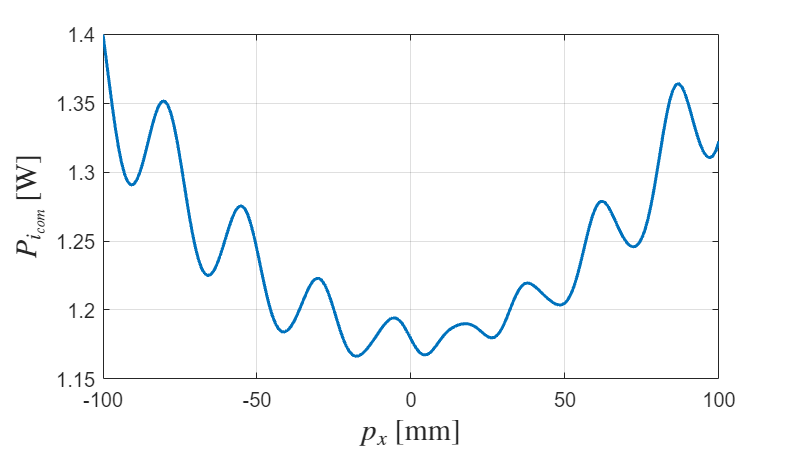

figure(1)
x0=150;
y0=150;
width=700;
height=400;
set(gcf,'position',[x0,y0,width,height])
plot(px_t,P_com_arr, 'LineWidth', 1.5)
grid on
ylabel('$P_{i_{com}}$ [W]', "FontSize", 15,'Interpreter','latex')
xlabel('$p_x$ [mm]', "FontSize", 15,'Interpreter','latex')
xlim(p_x_range)

Make plot for current distributions $i_{com}$:

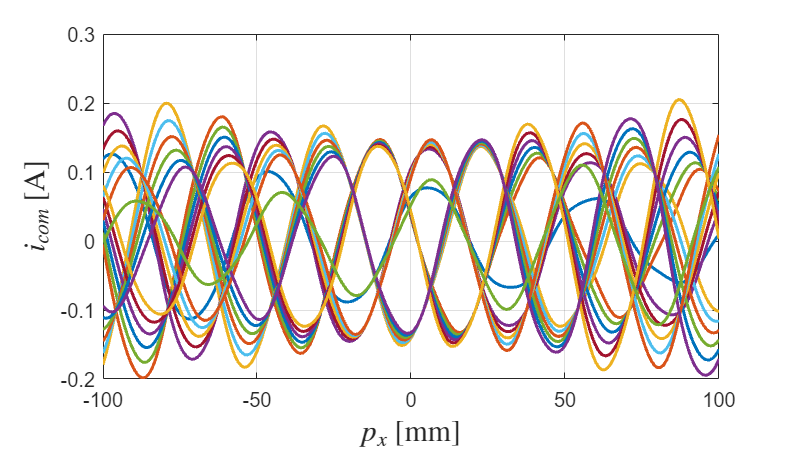

figure(1)
set(gcf,'position',[x0,y0,width,height])
plot(px_t,i_com_arr, 'LineWidth', 1.5)
grid on
ylabel('$i_{com}$ [A]', "FontSize", 15,'Interpreter','latex')
xlabel('$p_x$ [mm]', "FontSize", 15,'Interpreter','latex')
xlim(p_x_range)

### Question 7

Minimize the maximum current $i_k$

% test value for p_x = 80mm, because in this area the currents are larger
p_x_t = 80;

% gamma matrix
Gm_px = Gm_px_f(p_x_t);

% add one row of zeros to the eq constraint for variable x(K+1) = M
% so we have: [i_1, i_2, ..., i_k, M]
Gm_px = [Gm_px zeros([length(w_des),1])];

% equality constraint
Aeq = Gm_px;
beq = w_des;

% ineq constraint 
% variable x(K+1) = M

% -1*i_k - M <= 0
neg_ones = -1*ones([1,K+1]);
Aineq_neg = diag(neg_ones);
Aineq_neg(:, end) = -1;
Aineq_neg = Aineq_neg(1:end-1,:);

% i_k - M <= 0
pos_ones = -1*neg_ones;
Aineq_pos = diag(pos_ones);
Aineq_pos(:, end) = -1;
Aineq_pos = Aineq_pos(1:end-1,:);

% merge Aineq_pos and Aineq_neg
Aineq = [Aineq_pos; 
         Aineq_neg];
bineq = zeros(2*K,1);

% define the objective = M = x(K+1)
f = zeros([1,K+1]);
f(K+1) = 1;

% solve for i
[x,fval,exitflag,output,lambda] = linprog(f, Aineq, bineq, Aeq, beq);

Optimal solution found.



### Question 8

% create different values for p_x
px_t = p_x_range(1):p_x_range(2);
i_com_arr = zeros(K, length(px_t));

% loop over all p_x
for i = 1:length(px_t)
    % get p_x and its corresponding Gamma matrix
    Gm_i = Gm_px_f(px_t(i));

    % update equality constraints
    Aeq = [Gm_i zeros([length(w_des),1])];

    % solve for i
    [x,fval,exitflag,output,lambda] = linprog(f, Aineq, bineq, Aeq, beq);
    i_com = x(1:K);
    i_com_arr(:,i) = i_com; 
end

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solu

Make plot for current distributions $i_{com}$:

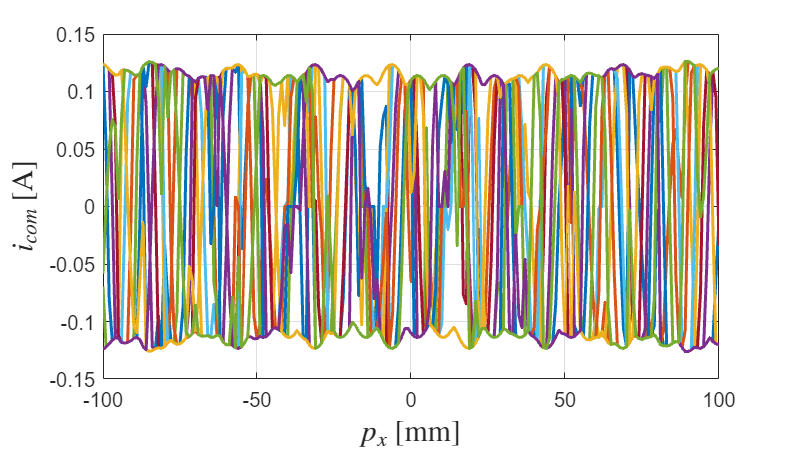

figure(1)
set(gcf,'position',[x0,y0,width,height])
plot(px_t,i_com_arr, 'LineWidth', 1.5)
grid on
ylabel('$i_{com}$ [A]', "FontSize", 15,'Interpreter','latex')
xlabel('$p_x$ [mm]', "FontSize", 15,'Interpreter','latex')
xlim(p_x_range)

### Question 9

% create different values for p_x
px_t = p_x_range(1):p_x_range(2);
i_com_arr = zeros(K, length(px_t));

% inequality constraints
bineq = zeros(2*K,1);
diag_nones = diag(-1 * ones(1,K));
Aineq = [diag_nones   zeros([K,K]);
         zeros([K,K]) diag_nones];

% equality constraints
beq = w_des;

% objective f = sum(i_plus) + sum(i_neg)
f = ones([2*K,1]);

% loop over all p_x
for i = 1:length(px_t)
    % get p_x and its corresponding Gamma matrix
    Gm_i = Gm_px_f(px_t(i));

    % update equality constraints
    Aeq = [Gm_i -Gm_i];

    % solve for i
    [x,fval,exitflag,output,lambda] = linprog(f, Aineq, bineq, Aeq, beq);

    % transform i+ and i- back to the original i
    % i = i_pos - i_neg
    i_com = x(1:K) - x(K+1:end);
    i_com_arr(:,i) = i_com; 
end

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solu

Make plot for current distributions $i_{com}$:

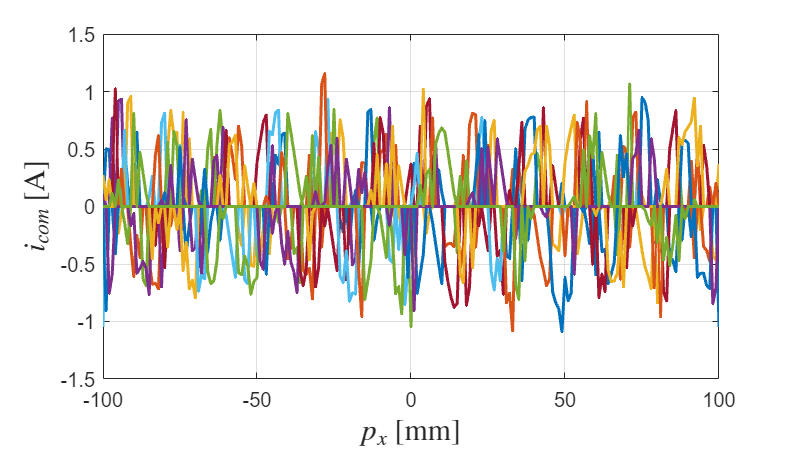

figure(1)
set(gcf,'position',[x0,y0,width,height])
plot(px_t,i_com_arr, 'LineWidth', 1.5)
grid on
ylabel('$i_{com}$ [A]', "FontSize", 15,'Interpreter','latex')
xlabel('$p_x$ [mm]', "FontSize", 15,'Interpreter','latex')
xlim(p_x_range)